% Load Data
SP500Index = SP500; % Importation of Daily closing S&P500 Index price for 3 year period
Stocks = FiftyStocks; % Importation of Daily closing Price of 50 USA Equity stocks 
returns = diff(Stocks)./ Stocks(1:end-1, :);
mean_returns = mean(returns) % Calculate mean returns

mean_returns =     0.0007    0.0004    0.0028   -0.0001    0.0001    0.0003    0.0004    0.0012    0.0006   -0.0002   -0.0007    0.0004    0.0001    0.0002    0.0003   -0.0008    0.0001    0.0001    0.0003    0.0003    0.0009    0.0002    0.0009    0.0005    0.0012    0.0000    0.0003    0.0004   -0.0001    0.0006    0.0005   -0.0000    0.0003    0.0008    0.0002    0.0001    0.0015    0.0010   -0.0000   -0.0002    0.0003   -0.0001    0.0004    0.0006    0.0001   -0.0002    0.0006    0.0010    0.0007    0.0005


annual_Avg_Returns = (1+mean_returns) .^252 -1 % Calculate mean returns

annual_Avg_Returns =     0.1937    0.1146    1.0229   -0.0225    0.0204    0.0671    0.1167    0.3527    0.1756   -0.0496   -0.1577    0.1175    0.0257    0.0568    0.0687   -0.1781    0.0131    0.0246    0.0667    0.0651    0.2484    0.0579    0.2596    0.1283    0.3645    0.0070    0.0759    0.1048   -0.0176    0.1738    0.1259   -0.0073    0.0781    0.2087    0.0635    0.0143    0.4407    0.2774   -0.0013   -0.0414    0.0735   -0.0203    0.0958    0.1503    0.0139   -0.0501    0.1559    0.2769    0.2057    0.1446


cov_matrix = cov(returns); % Calculating the covariance matrix for 50 Stocks
Yearly_CovMatrix = cov_matrix * 252 % Converted the daily covariance to yearly by scalar multiplication of 252 days of Trading

Yearly_CovMatrix =     0.0760    0.0525    0.0878    0.0588    0.0295    0.0440    0.0560    0.0670    0.0595    0.0093    0.0297    0.0596    0.0872    0.0320    0.0172    0.0466    0.0367    0.0147    0.0133    0.0146    0.0344    0.0160    0.0134    0.0144    0.0158    0.0080    0.0076    0.0156    0.0298    0.0137    0.0242    0.0271    0.0310    0.0371    0.0531    0.0270    0.0325    0.0242    0.0251    0.0349    0.0319    0.0229    0.0315    0.0271    0.0227    0.0111    0.0128    0.0199    0.0134    0.0178
    0.0525    0.0768    0.1005    0.0701    0.0284    0.0436    0.0629    0.0802    0.0612    0.0049    0.0277    0.0718    0.0712    0.0312    0.0152    0.0418    0.0346    0.0131    0.0139    0.0128    0.0348    0.0155    0.0067    0.0100    0.0142    0.0063    0.0058    0.0146    0.0321    0.0122    0.0223    0.0259    0.0322    0.0361    0.0633    0.0286    0.0314    0.0219    0.0251    0.0325    0.0352    0.0206    0.0310    0.0292    0.0212    0.0072    0.0098    0.0194

risk_free_rate = 0.0448 % Yearly risk-free rate

risk_free_rate = 0.0448


% Calculate Sharpe Ratios for all stocks
std_dev = std(returns) * sqrt(252) % Standard deviation of each stock

std_dev =     0.2758    0.2771    0.5665    0.3844    0.2362    0.2761    0.3213    0.4880    0.4908    0.2259    0.3671    0.3802    0.6093    0.2497    0.1741    0.3449    0.3261    0.1698    0.1759    0.1590    0.2429    0.1852    0.2764    0.2577    0.3254    0.1650    0.2095    0.2322    0.2558    0.2643    0.2415    0.2752    0.2760    0.2935    0.3836    0.3527    0.3034    0.2923    0.2040    0.2848    0.2877    0.2455    0.2839    0.2223    0.2806    0.2350    0.1958    0.2261    0.2064    0.3825


sharpe_ratios = (annual_Avg_Returns - risk_free_rate) ./ std_dev % Sharpe Ratios

sharpe_ratios =     0.5399    0.2520    1.7266   -0.1751   -0.1031    0.0806    0.2238    0.6310    0.2665   -0.4178   -0.5516    0.1912   -0.0313    0.0480    0.1370   -0.6462   -0.0972   -0.1191    0.1243    0.1276    0.8383    0.0710    0.7770    0.3241    0.9825   -0.2288    0.1483    0.2584   -0.2438    0.4882    0.3359   -0.1893    0.1208    0.5583    0.0488   -0.0865    1.3052    0.7958   -0.2259   -0.3028    0.0998   -0.2651    0.1797    0.4747   -0.1099   -0.4036    0.5677    1.0268    0.7798    0.2609


**PART TWO**

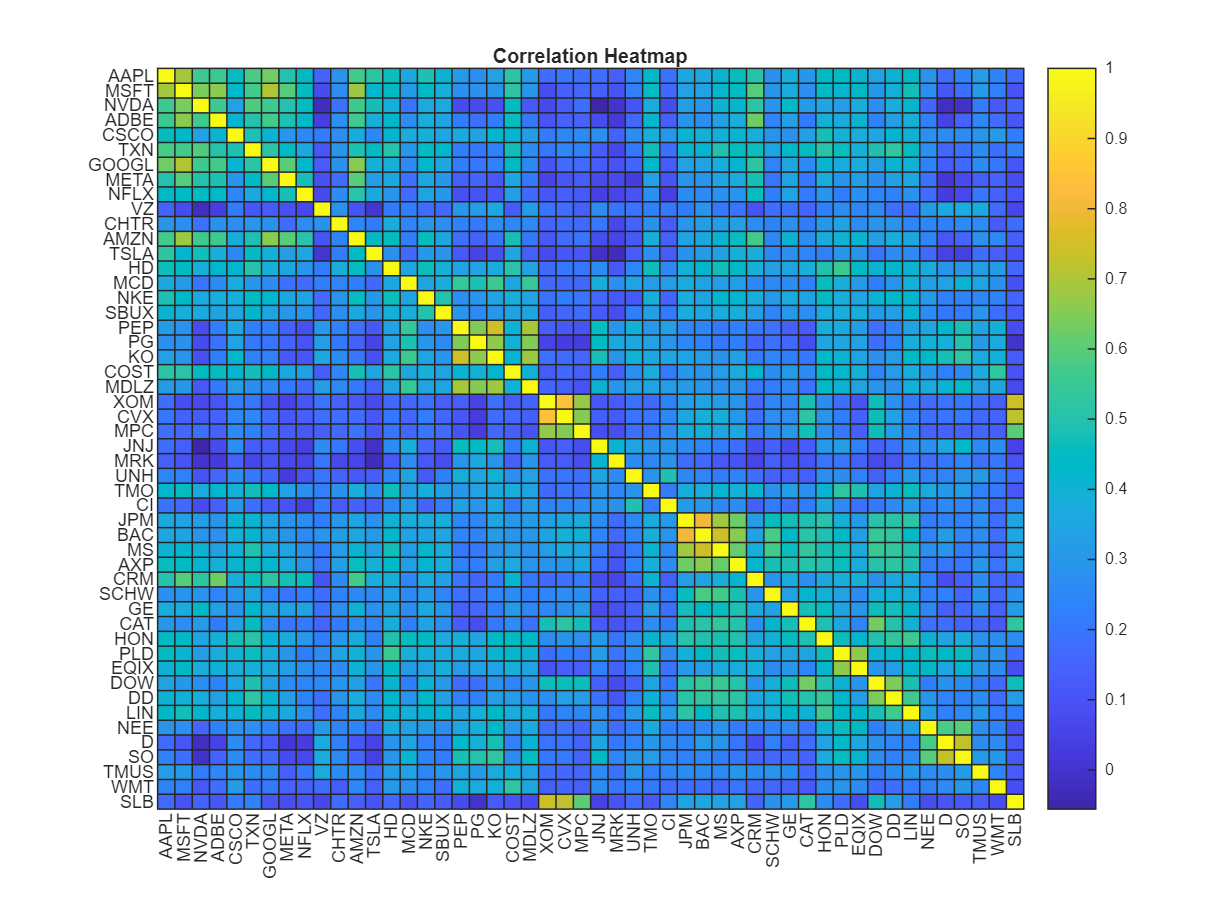

% Computing the Correlation Matrix
corr_matrix = corr(returns); % Compute the correlation matrix

% Heatmap for the Correlation of Stocks.
h = heatmap(stock_names, stock_names, corr_matrix, 'Colormap', parula);
title('Correlation Heatmap')
h.FontSize = 6;


% Removing the diagonal elements
n = size(corr_matrix, 1); % Number of stocks
off_diag_corr = corr_matrix;
off_diag_corr(1:n+1:end) = NaN % Set diagonal elements to NaN

off_diag_corr =        NaN    0.6869    0.5623    0.5551    0.4524    0.5780    0.6317    0.4979    0.4398    0.1491    0.2930    0.5686    0.5193    0.4646    0.3588    0.4895    0.4086    0.3150    0.2734    0.3333    0.5135    0.3129    0.1752    0.2033    0.1766    0.1767    0.1314    0.2439    0.4228    0.1886    0.3640    0.3565    0.4072    0.4585    0.5018    0.2771    0.3880    0.3001    0.4464    0.4447    0.4022    0.3389    0.4028    0.4424    0.2935    0.1720    0.2363    0.3185    0.2346    0.1688
    0.6869       NaN    0.6405    0.6579    0.4345    0.5696    0.7060    0.5928    0.4497    0.0782    0.2723    0.6816    0.4219    0.4502    0.3142    0.4372    0.3829    0.2777    0.2852    0.2905    0.5171    0.3027    0.0875    0.1394    0.1575    0.1378    0.0996    0.2268    0.4535    0.1668    0.3332    0.3399    0.4211    0.4443    0.5951    0.2927    0.3738    0.2704    0.4448    0.4113    0.4420    0.3036    0.3942    0.4749    0.2733    0.1102    0.1810    0.3094   


% Step 3: Find correlations closest to 0
[~, indices] = mink(abs(off_diag_corr(:)), 7); % Find 20 correlations closest to 0
[row_indices, col_indices] = ind2sub(size(corr_matrix), indices); % Get stock pairs

% Step 4: Extract unique stocks
selected_stocks = unique([row_indices; col_indices]); % Unique stocks in these pairs
selected_returns = annual_Avg_Returns(selected_stocks)'; % Ensure it’s a column vector
selected_cov = Yearly_CovMatrix(selected_stocks, selected_stocks);

% Risk Aversion Input (0: High Risk Aversion, 1: Low Risk Aversion)
risk_aversion = 1 % Enter Risk Aversion Level (0 = High Risk Averse, 1 = Low Risk Averse)

risk_aversion = 1


% Define Risk Aversion Factor (λ): High risk aversion => Low λ
lambda = 1 - risk_aversion % Adjust to match risk aversion level

lambda = 0


% Quadratic Programming Inputs
n = length(selected_stocks) % Number of selected stocks

n = 7

H = 2 * ((1 - lambda) * selected_cov) % Quadratic term (2 * covariance matrix)

H =     0.6418    0.3273    0.0156   -0.0104    0.0010   -0.0007    0.0642
    0.3273    0.7425    0.0115   -0.0014   -0.0067    0.0110    0.0454
    0.0156    0.0115    0.0619    0.0259    0.0268    0.0343    0.0001
   -0.0104   -0.0014    0.0259    0.0545    0.0284    0.0284    0.0062
    0.0010   -0.0067    0.0268    0.0284    0.0878    0.0202    0.0159
   -0.0007    0.0110    0.0343    0.0284    0.0202    0.0767    0.0181
    0.0642    0.0454    0.0001    0.0062    0.0159    0.0181    0.2926


f = -lambda * selected_returns % Linear term (-expected returns)

f =      0
     0
     0
     0
     0
     0
     0



% Constraints
Aeq = ones(1, n); % Equality constraint: sum of weights = 1
beq = 1;
lb = zeros(n, 1); % No short selling
ub = ones(n, 1); % Max weight = 1 per stock

% Solve the optimization problem using quadprog
opts = optimoptions('quadprog', 'Display', 'off'); % Quadprog options
[optimal_weights, ~] = quadprog(H, f, [], [], Aeq, beq, lb, ub, [], opts);

% Portfolio Metrics
portfolio_return = sum(optimal_weights .* selected_returns);
portfolio_variance = optimal_weights' * selected_cov * optimal_weights;
portfolio_risk = sqrt(portfolio_variance);
portfolio_sharpe = (portfolio_return - risk_free_rate) / portfolio_risk;

% Display Results
disp('Optimal Portfolio Weights:');

Optimal Portfolio Weights:


disp(optimal_weights);

    0.0323
    0.0218
    0.2384
    0.3428
    0.1488
    0.1372
    0.0787



disp('Portfolio Expected Return:');

Portfolio Expected Return:


disp(portfolio_return);

    0.0959



disp('Portfolio Risk (Std Dev):');

Portfolio Risk (Std Dev):


disp(portfolio_risk);

    0.1286



disp('Portfolio Sharpe Ratio:');

Portfolio Sharpe Ratio:


disp(portfolio_sharpe);

    0.3976



disp('Selected Stocks (Indices):');

Selected Stocks (Indices):


disp(selected_stocks)

     3
    13
    19
    26
    27
    47
    50



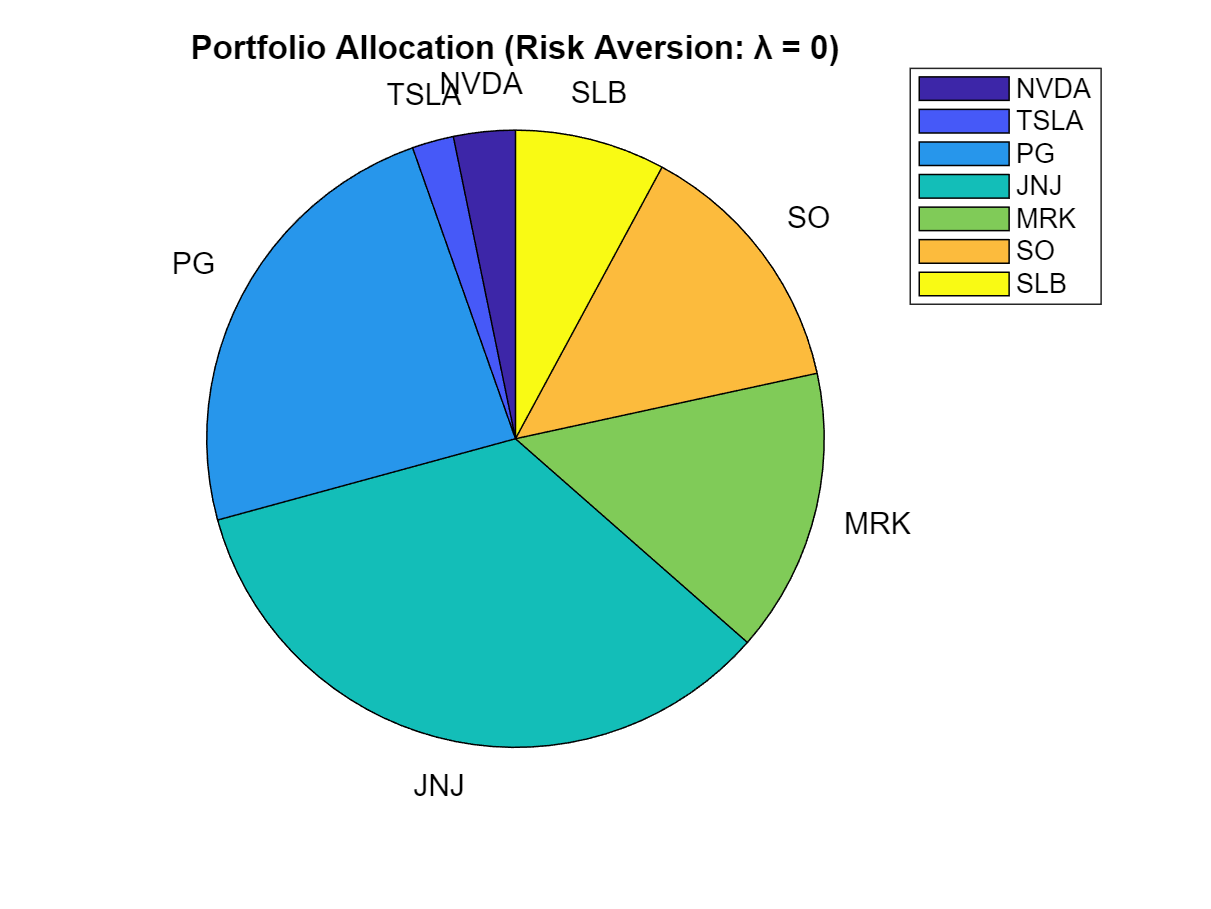


% Display Portfolio Allocation Pie Chart
stock_names =  StockNames.Properties.VariableNames; % Stock Names
selected_names = stock_names(selected_stocks);
figure;
pie(optimal_weights, selected_names); % Use weights and stock names
title(['Portfolio Allocation (Risk Aversion: λ = ', num2str(lambda), ')']);
legend(selected_names, 'Location', 'bestoutside');

**Efficient Frontier**

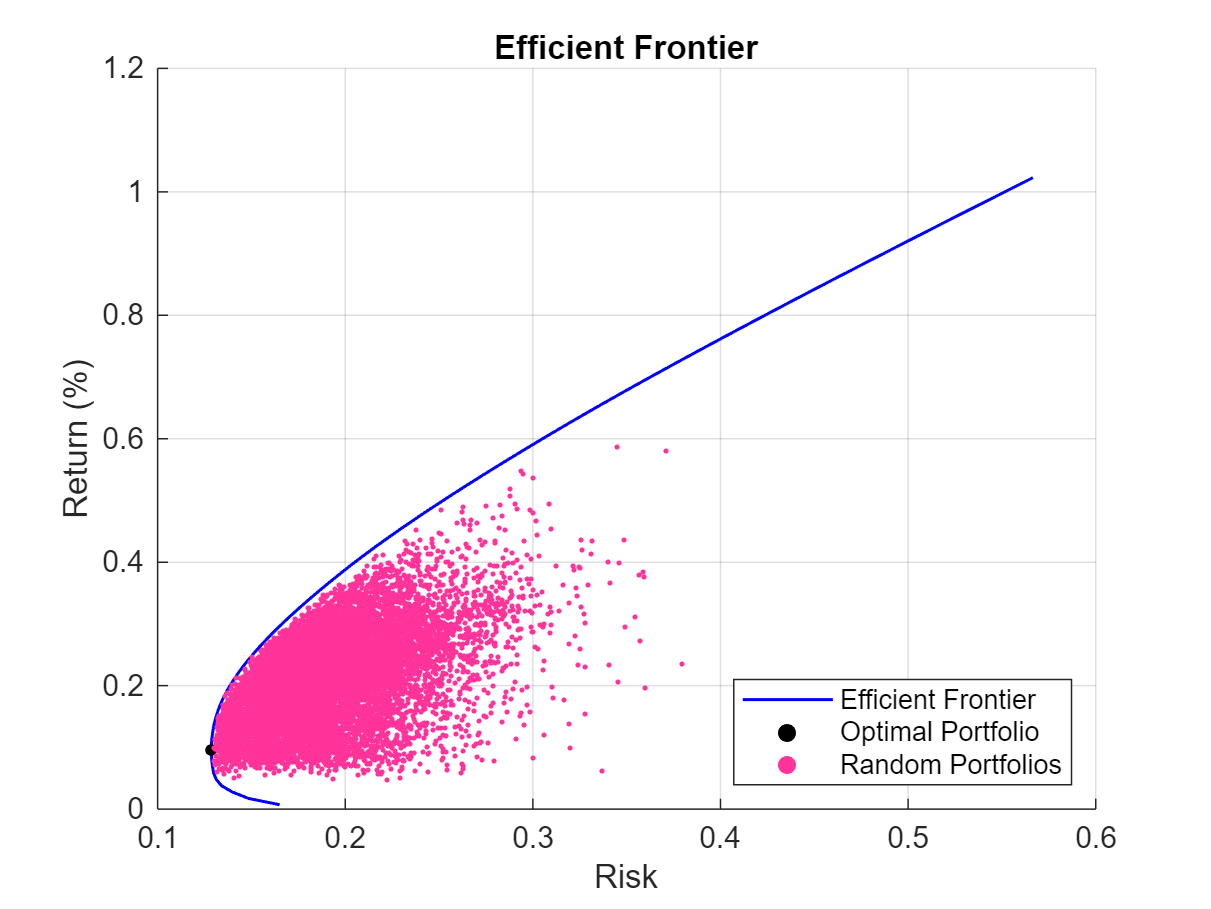

% Generate Target Returns for Efficient Frontier
num_portfolios = 100; % Number of portfolios to simulate
target_returns = linspace(min(selected_returns), max(selected_returns), num_portfolios); % Range of target returns

% Initialize Arrays for Efficient Frontier Metrics
portfolio_risks = zeros(1, num_portfolios);
portfolio_returns = zeros(1, num_portfolios);
portfolio_weights = zeros(n, num_portfolios);

% Loop Through Target Returns to Compute Efficient Frontier
for i = 1:num_portfolios
    % Set equality constraints for the target return
    Aeq = [ones(1, n); selected_returns'];
    beq = [1; target_returns(i)];
    
    % Solve the quadratic programming problem for each target return
    [weights, ~] = quadprog(selected_cov, [], [], [], Aeq, beq, lb, ub, [], opts);
    
    % Store portfolio weights, return, and risk
    portfolio_weights(:, i) = weights;
    portfolio_returns(i) = weights' * selected_returns;
    portfolio_risks(i) = sqrt(weights' * selected_cov * weights);
end

% Plot Efficient Frontier
figure;
hold on;

% Plot Efficient Frontier Curve
plot(portfolio_risks, portfolio_returns, 'b-', 'LineWidth', 1, 'DisplayName', 'Efficient Frontier');

% Highlight the Optimal Portfolio
optimal_risk = portfolio_risk; % From the optimal portfolio
optimal_return = portfolio_return; % From the optimal portfolio
scatter(optimal_risk, optimal_return, 15, 'k', 'filled', 'DisplayName', 'Optimal Portfolio');

% Random Portfolios (Optional Visualization)
num_random = 10000;
random_risks = zeros(1, num_random);
random_returns = zeros(1, num_random);

for i = 1:num_random
    random_weights = rand(n, 1);
    random_weights = random_weights / sum(random_weights); % Normalize weights
    random_returns(i) = random_weights' * selected_returns;
    random_risks(i) = sqrt(random_weights' * selected_cov * random_weights);
end
scatter(random_risks, random_returns, 3, [1, 0.2, 0.6], 'filled', 'DisplayName', 'Random Portfolios');

% Add Labels, Title, and Legend
xlabel('Risk');
ylabel('Return (%)');
title('Efficient Frontier');
legend('show', 'Location', 'southeast'); % Move legend to bottom-right corner
grid on;
hold off;

**Effecient Frontier with Tangent Line**

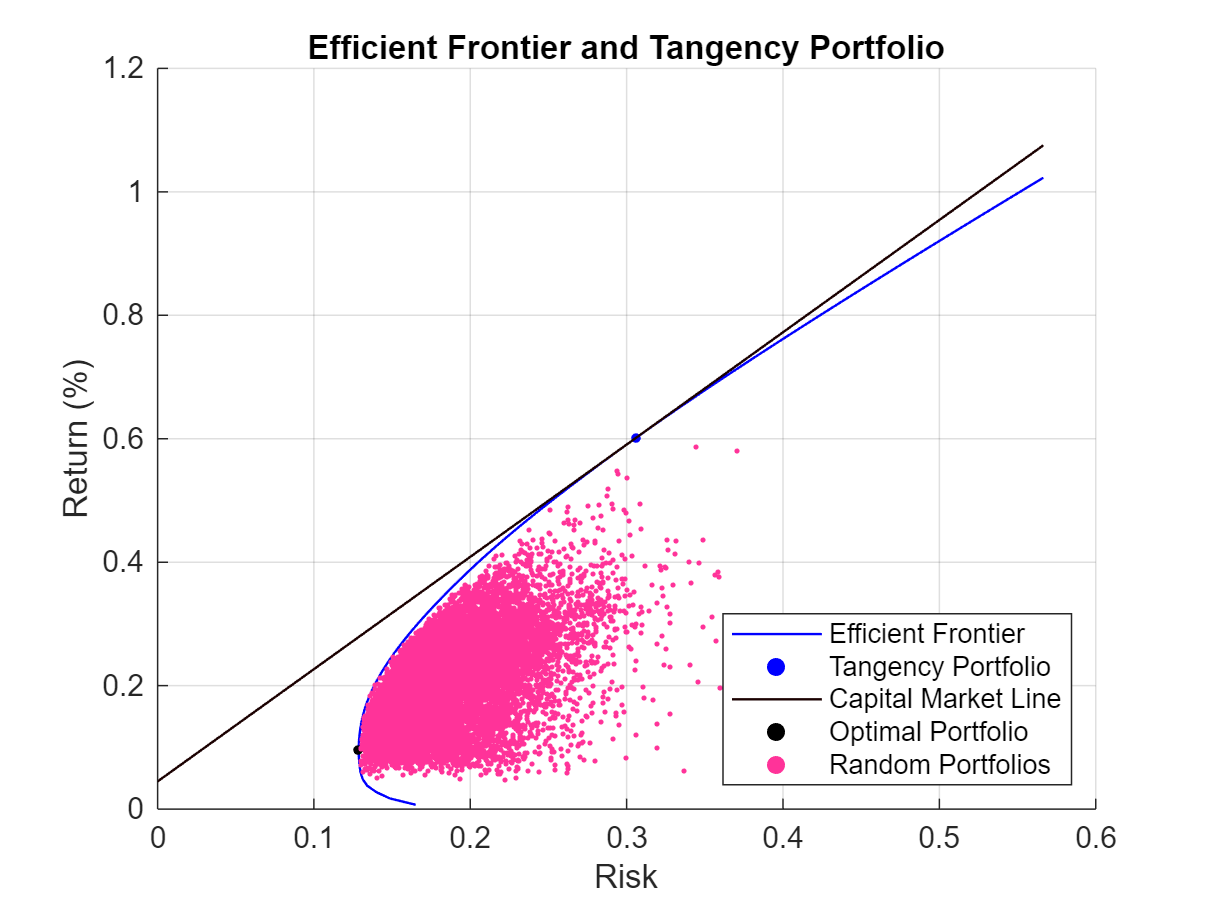


% Step 1: Compute Sharpe Ratios for Efficient Frontier
sharpe_ratio = (portfolio_returns - risk_free_rate) ./ portfolio_risks;

% Step 2: Find the Tangency Portfolio
[max_sharpe, max_index] = max(sharpe_ratio); % Maximum Sharpe Ratio
tangency_weights = portfolio_weights(:, max_index); % Weights of the tangency portfolio
tangency_return = portfolio_returns(max_index); % Return of tangency portfolio
tangency_risk = portfolio_risks(max_index); % Risk of tangency portfolio

% Step 3: Plot Efficient Frontier and Tangency Portfolio
figure;
hold on;

% Plot Efficient Frontier
plot(portfolio_risks, portfolio_returns, 'b-', 'LineWidth', 0.8, 'DisplayName', 'Efficient Frontier');

% Highlight Tangency Portfolio
scatter(tangency_risk, tangency_return, 10, 'b', 'filled', 'DisplayName', 'Tangency Portfolio'); % Blue point

% Plot Capital Market Line (CML)
cml_risks = linspace(0, max(portfolio_risks), 100); % Generate risk levels for CML
cml_returns = risk_free_rate + max_sharpe * cml_risks; % CML equation
plot(cml_risks, cml_returns, 'Color', [0.1, 0, 0], 'LineStyle', '-', 'LineWidth', 0.8, 'DisplayName', 'Capital Market Line'); % Dark red line

% Highlight the Optimal Portfolio (from your efficient frontier)
scatter(optimal_risk, optimal_return, 10, 'k', 'filled', 'DisplayName', 'Optimal Portfolio'); % Black point

% Add Random Portfolios (Optional)
scatter(random_risks, random_returns, 3, [1, 0.2, 0.6], 'filled', 'DisplayName', 'Random Portfolios');

% Add Labels, Title, and Legend
xlabel('Risk');
ylabel('Return (%)');
title('Efficient Frontier and Tangency Portfolio');
legend('show', 'Location', 'southeast');
grid on;
hold off;


% Step 4: Display Tangency Portfolio and Optimal Portfolio Metrics
disp('Tangency Portfolio:');

Tangency Portfolio:


disp([' - Return: ', num2str(tangency_return * 100), '%']);

 - Return: 60.2187%


disp([' - Risk: ', num2str(tangency_risk * 100), '%']);

 - Risk: 30.6369%


disp([' - Sharpe Ratio: ', num2str(max_sharpe)]);

 - Sharpe Ratio: 1.8193



disp('Optimal Portfolio:');

Optimal Portfolio:


disp([' - Return: ', num2str(optimal_return * 100), '%']);

 - Return: 9.5948%


disp([' - Risk: ', num2str(optimal_risk * 100), '%']);

 - Risk: 12.8634%


disp([' - Sharpe Ratio: ', num2str((optimal_return - risk_free_rate) / optimal_risk)]);

 - Sharpe Ratio: 0.39762
